# 自适应极点配置

I.D.Landau等人的控制器设计结合了固定控制器与自适应控制器设计。

与Carmona等人的研究相近，固定控制器的设计采用了基于极点配置的灵敏度函数塑形方法，在目标频率引入了陷波。

## 1 仿真环境基本配置

仿真沿用Carmona2000.mlx中的实验设置与控制器初设计，不再另外设置。如果需要运行当前程序，请先运行Carmona2000。

### 1.1 主噪声/扰动设置

参考Landau等人论文中的设计方法

Ns = 2000;
t = linspace(0,Ns*Ts,Ns);
% 扰动信号（多频正弦噪声信号）模型设计
f = [100, 200]; % 两个频率 (Hz)
A = [1, 1];   % 幅值可任意指定
syms z n

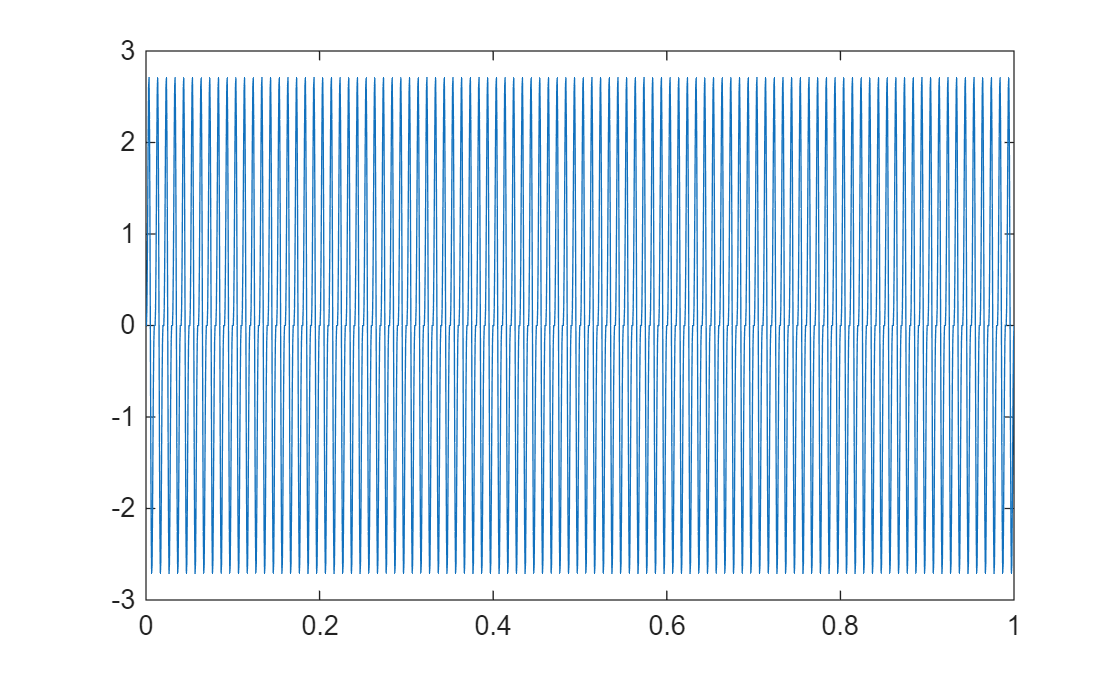


Np_all = 1;
Dp_all = 1;
for i = 1:length(f)
    sin_wave = A(i) * sin(2*pi*f(i)*n*Ts);
    Z_transform = simplify(ztrans(sin_wave));
    [num, den] = numden(Z_transform);
    Np = double(flip(coeffs(num, z, 'All')));
    Dp = double(flip(coeffs(den, z, 'All')));
    % 卷积叠加各频率的滤波器
    Np_all = conv(Np_all, Np);
    Dp_all = conv(Dp_all, Dp);
end
disturbance = filter(Np_all, Dp_all, [1, zeros(1, length(t)-1)]);
figure; plot(t, disturbance);

### 1.2 标称控制器设计

所有极点都在单位圆内，系统稳定。


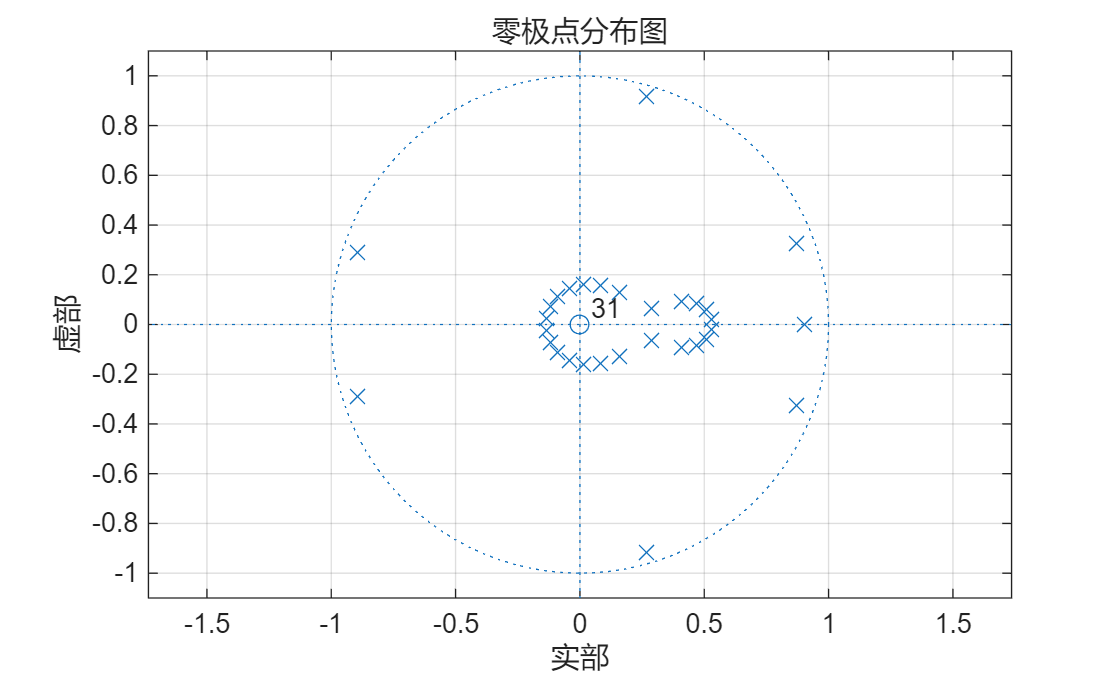

% 系统定义
Ao = A_coeffs;
Bo = [zeros(1,d),B_coeffs];
Bo_star = B(2:end);
% 中心控制器设计（已完成）
Ro = R_K1;
So = S_K1;
C0 = tf(Ro, So, Ts); % Central controller
HS = SS1;
HR = RS1;
% 特征多项式
Po = addPolynomials(conv(Ao,So),conv(Bo,Ro));
isschur(Po);

所有极点都在单位圆内，系统稳定。


%% 定义存在不确定性的系统模型
% Delta = [0, 0.09, -0.09];
% Gamma = [1, -1.4, 0.45];
% [A, B] = mapping(Ao, Bo, So, Ro, Delta, Gamma, 2);
A = Ao; B = Bo;
B_star = B(2:end);

nQ = 2; % Order of the Q filter
Q = zeros(1,nQ+1);
Q0 = Q;

P1 = addPolynomials(conv(A,So),conv(B,Ro));
isschur(P1);

% P2 = addPolynomials(Gamma,HR*HS*conv(Q0,Delta));
% isschur(P2);     

## 2 RLS参数自适应迭代

`参数自适应算法（如最小二乘法RLS、递推最小二乘RLS、LMS等）广泛用于自适应控制和信号处理。其核心思想是通过在线调整参数，使系统输出逼近期望目标。以RLS为例，参数更新公式为：`


$$\theta_{k+1} = \theta_k + F_k \Phi_k^T e_k$$


`其中`$F_k$`为协方差矩阵，`$\Phi_k$`为回归向量，`$e_k$`为误差。`$F_k$`的更新通常为：`


$$F_{k+1}^{-1} = \lambda_1 F_k^{-1} + \lambda_2 \Phi_k^T \Phi_k$$


$\lambda_1$`为遗忘因子，`$\lambda_2$`为增益。`

`在实际工程中，参数自适应算法常出现如下数值不稳定现象``：`

`-`` 协方差矩阵F奇异或接近奇异，导致反演失败或数值爆炸。`

`-`` 参数Q发散，系统输出异常。`

`-`` 误差累积，最终算法失效。`

`主要原因包括``：`

`-`` F初值过大或过小，导致数值溢出或下溢。`

`-`` 遗忘因子`$\lambda_1
$`过大，历史数据影响过强。`

`-`` 回归向量`$\Phi$`长期为零或变化缓慢，F更新退化。`

`-`` 干扰信号或系统模型不匹配。`

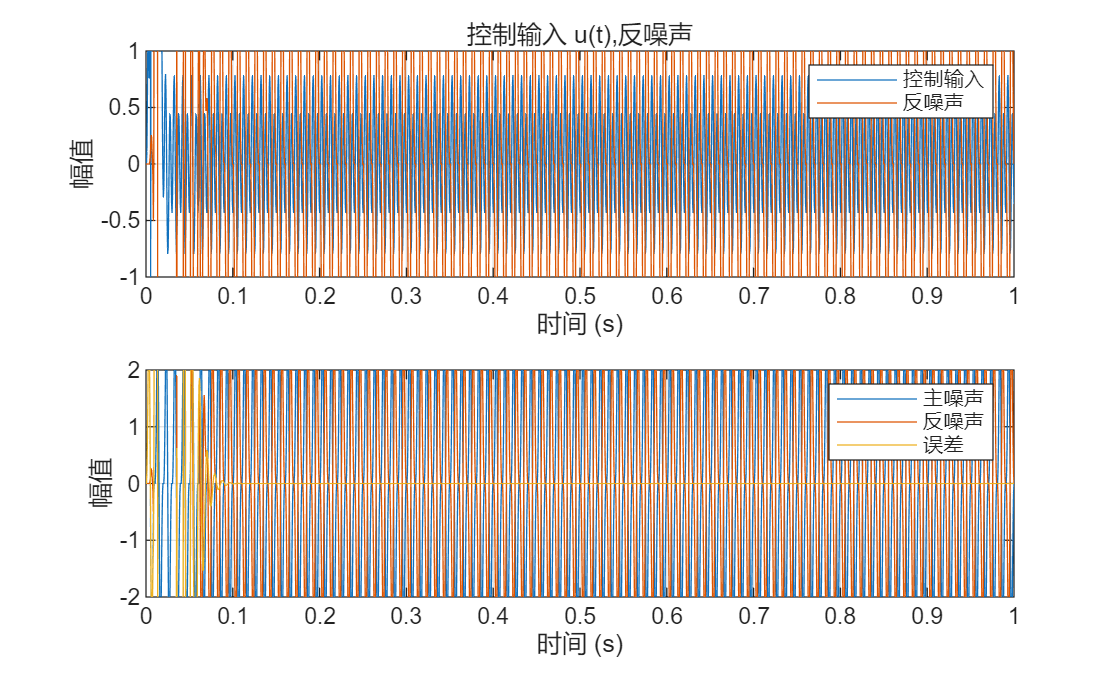

%% 自适应参数初始化
lambda1 = 0.98; % Forgetting factor
lambda2 = 1; % Adaptation gain
nB = length(B)-1;
nA = length(A);
nS = length(So);

Phi = zeros(1,nQ+1);
F = 10e3.*eye(nQ+1);

N = max([nA, nB, nS, length(Po)]);
U = zeros(1,N);
Y = zeros(1,N);
Yf = zeros(1,N);
W = zeros(1,N);
W1 = zeros(1,N);
W2 = zeros(1,N);

%% 自适应仿真循环
u = zeros(size(t)); % Control input
y = zeros(size(t)); % System output
antinoise = zeros(size(t));
w = zeros(size(t)); % Observer output
w1 = zeros(size(t));
w2 = zeros(size(t));
e0 = zeros(size(t)); % Adaptation error
e = zeros(size(t)); % Adaptation error

for k = 1:length(t)
    
    % Plant输出的测量
    antinoise(k) = FIR(B(2:end),U) - FIR(A(2:end),Yf);
    Yf = [antinoise(k), Yf(1:end-1)];
    y(k) = antinoise(k) + disturbance(k);
    Y = [y(k),Y(1:end-1)];

    % 扰动观测值
    w(k) = FIR(A, Y) - FIR(Bo_star, U);
    W = [w(k),W(1:end-1)];
    w1(k) = FIR(So, W) - FIR(Po(2:end), W1);
    W1 = [w1(k),W1(1:end-1)];
    % 先验/后验误差
    e0(k) = w1(k) - FIR(Q, Phi);
    % 自适应参数更新
    e(k) = e0(k)/(1+Phi*F*Phi.');
    Q = Q + (F * Phi' * e(k))';

    
    % 计算控制输入
    u(k) = -FIR(Ro, Y) - FIR(conv(conv(HR,HS),Q), W) - FIR(So(2:end), U);
    % 饱和 
    % u(k) = sat(u(k),5);
    U = [u(k), U(1:end-1)];
    
    % 为下一时刻做准备
    w2(k) =  FIR(conv(conv(HR,HS),Bo_star), W) - FIR(Po(2:end), W2);
    W2 = [w2(k), W2(1:end-1)];
    Phi = [w2(k), Phi(1:end-1)];
    F_new = lambda1.* inv(F) + lambda2 .* (Phi' * Phi);
    F_new = F_new + 1e-8*eye(size(F_new));
    F = inv(F_new);
    if any(isnan(F(:))) || any(isinf(F(:))) || rcond(F) < 1e-12
        error('F矩阵奇异或数值不稳定，脚本已终止。');
    end
end
%% 初始化绘图窗口
figure('Name','实时信号处理','NumberTitle','off');
subplot(2,1,1);
plot(t, u, 'DisplayName', '控制输入'); hold on;
plot(t, antinoise, 'DisplayName', '反噪声');
grid on;
title('控制输入 u(t),反噪声');
legend('show');
xlabel('时间 (s)'); ylabel('幅值');
xlim([0 t(end)]); 
ylim([-1 1]);
subplot(2,1,2);
plot(t, disturbance, 'DisplayName', '主噪声'); hold on;
plot(t, antinoise, 'DisplayName', '反噪声');
plot(t, y, 'DisplayName', '误差');
grid on;
legend('show');
xlabel('时间 (s)'); ylabel('幅值');
xlim([0 t(end)]); 
ylim([-2 2]);

## 3 LMS参数自适应迭代

在Landau等人的研究中，使用$\phi \;{\left(t\right)}^{\top \;} \hat{\theta \;} \left(t\right)$与经过滤波的估计干扰$w_1 \left(t\right)$合成了一个“误差信号”$\varepsilon \;\left(t\right)$，并使用RLS算法进行参数自适应。

此处的RLS算法能否使用LMS算法替代呢？可以试试。

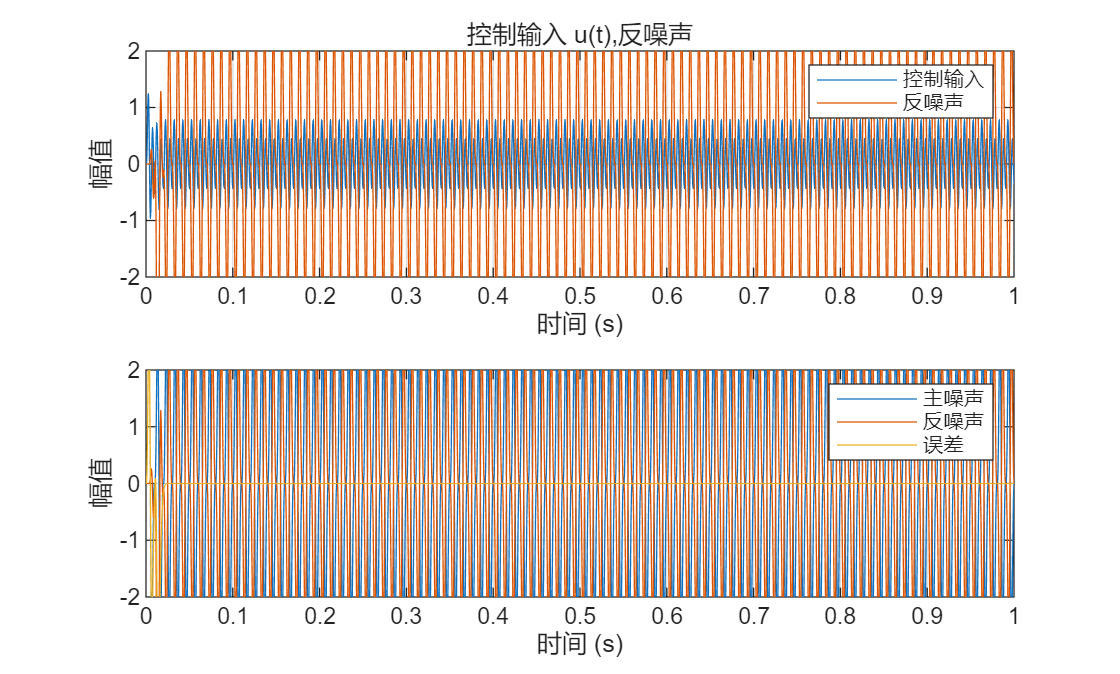

Q = zeros(1,nQ+1);
%% 自适应参数初始化
stepSize = 1e-7; 
nB = length(B)-1;
nA = length(A);
nS = length(So);

Phi = zeros(1,nQ+1);
F = 10e3.*eye(nQ+1);

N = max([nA, nB, nS, length(Po)]);
U = zeros(1,N);
Y = zeros(1,N);
Yf = zeros(1,N);
W = zeros(1,N);
W1 = zeros(1,N);
W2 = zeros(1,N);

%% 自适应仿真循环
u = zeros(size(t)); % Control input
y = zeros(size(t)); % System output
antinoise = zeros(size(t));
w = zeros(size(t)); % Observer output
w1 = zeros(size(t));
w2 = zeros(size(t));
e0 = zeros(size(t)); % Adaptation error
e = zeros(size(t)); % Adaptation error

for k = 1:length(t)
    
    % Plant输出的测量
    antinoise(k) = FIR(B(2:end),U) - FIR(A(2:end),Yf);
    Yf = [antinoise(k), Yf(1:end-1)];
    y(k) = antinoise(k) + disturbance(k);
    Y = [y(k),Y(1:end-1)];

    % 扰动观测值
    w(k) = FIR(A, Y) - FIR(Bo_star, U);
    W = [w(k),W(1:end-1)];
    w1(k) = FIR(So, W) - FIR(Po(2:end), W1);
    W1 = [w1(k),W1(1:end-1)];
    % 先验/后验误差
    e0(k) = w1(k) - FIR(Q, Phi);
    % 自适应参数更新（LMS）
    Q = Q + stepSize.* Phi* e0(k);

    % 计算控制输入
    u(k) = -FIR(Ro, Y) - FIR(conv(conv(HR,HS),Q), W) - FIR(So(2:end), U);
    % 饱和 
    % u(k) = sat(u(k),5);
    U = [u(k), U(1:end-1)];
    
    % 为下一时刻做准备
    w2(k) =  FIR(conv(conv(HR,HS),Bo_star), W) - FIR(Po(2:end), W2);
    W2 = [w2(k), W2(1:end-1)];
    Phi = [w2(k), Phi(1:end-1)];
    % F_new = lambda1.* inv(F) + lambda2 .* (Phi' * Phi);
    % F_new = F_new + 1e-8*eye(size(F_new));
    % F = inv(F_new);
    % if any(isnan(F(:))) || any(isinf(F(:))) || rcond(F) < 1e-12
    %     error('F矩阵奇异或数值不稳定，脚本已终止。');
    % end
end

%% 初始化绘图窗口
figure('Name','实时信号处理','NumberTitle','off');
subplot(2,1,1);
plot(t, u, 'DisplayName', '控制输入'); hold on;
plot(t, antinoise, 'DisplayName', '反噪声');
grid on;
title('控制输入 u(t),反噪声');
legend('show');
xlabel('时间 (s)'); ylabel('幅值');
xlim([0 t(end)]); 
ylim([-2 2]);
subplot(2,1,2);
plot(t, disturbance, 'DisplayName', '主噪声'); hold on;
plot(t, antinoise, 'DisplayName', '反噪声');
plot(t, y, 'DisplayName', '误差');
grid on;
legend('show');
xlabel('时间 (s)'); ylabel('幅值');
xlim([0 t(end)]); 
ylim([-2 2]);

## 4 时变噪声信号仿真

### 4.1 时变信号生成

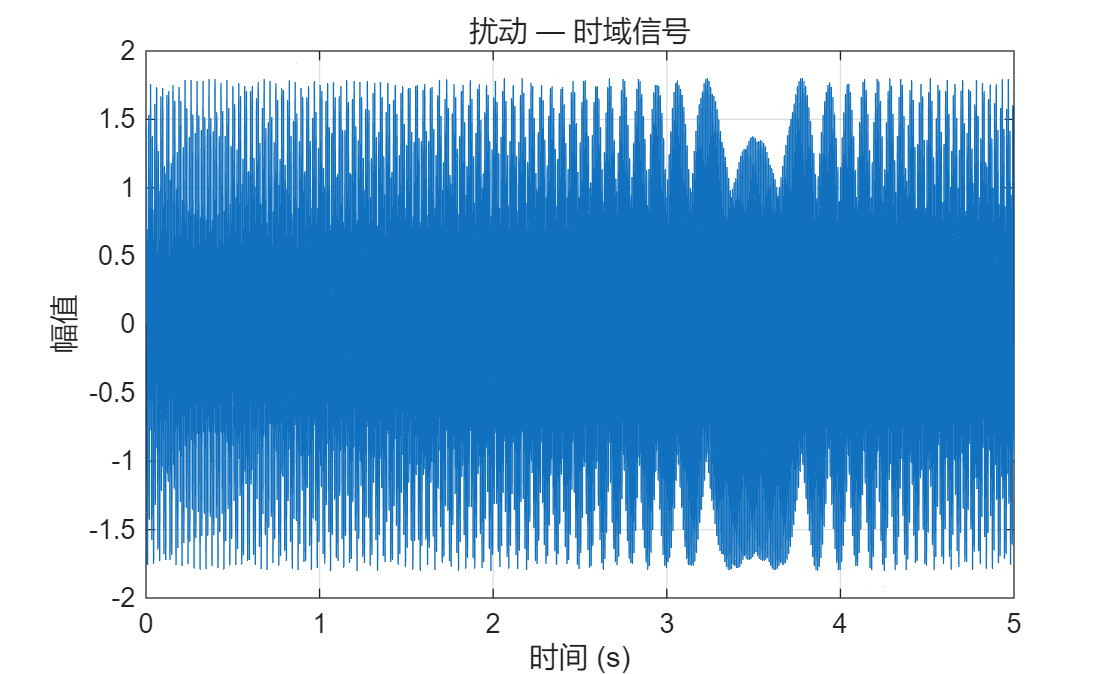

Ns = 10000;
t = linspace(0,Ns*Ts,Ns);
Amp = [1.0, 0.8];                           % 两个分量幅值
varfreq = 15;
f1_t = linspace(100-varfreq, 100+varfreq, length(t));     % 分量1：线性扫频 80 -> 120 Hz
f2_t = 200 + varfreq*sin(2*pi*0.1*t);           % 分量2：正弦调频，中心190Hz，幅度20Hz，调制速率1Hz
% 相位由瞬时频率积分得到
phi1 = 2*pi*cumtrapz(t, f1_t);
phi2 = 2*pi*cumtrapz(t, f2_t);
sig1 = Amp(1) * sin(phi1);
sig2 = Amp(2) * sin(phi2);
disturbance = sig1 + sig2;              
% 计算解析信号以得到包络与瞬时频率
analytic_sig = hilbert(disturbance);
inst_envelope = abs(analytic_sig);
inst_phase = unwrap(angle(analytic_sig));
inst_freq = [0, (Fs/(2*pi)) * diff(inst_phase)]; % Hz，长度与 t 一致

% 绘制时域与时频图供分析（可移到文件末尾）
figure('Name','扰动时域与时频图','NumberTitle','off');
plot(t, disturbance);
xlabel('时间 (s)'); ylabel('幅值');
title('扰动 — 时域信号');
xlim([0 t(end)]);
grid on;

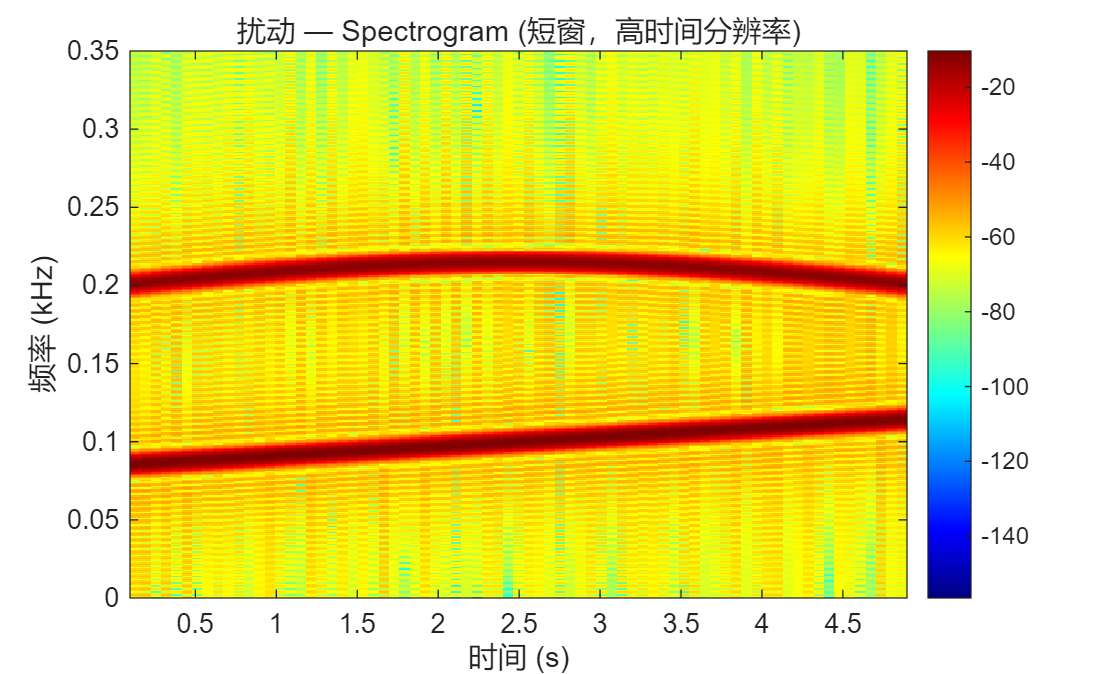

% 改进的 spectrogram：更短窗以提高时间分辨率，并在上面叠加瞬时频率
win = 512;                 % 较短窗，提升时间分辨率
overlap = round(0.75*win);
nfft = 2*1024;
figure('Name','扰动时频图（高时间分辨率）','NumberTitle','off');
spectrogram(disturbance, hamming(win), overlap, nfft, Fs, 'yaxis');
title('扰动 — Spectrogram (短窗，高时间分辨率)');
ylim([0 0.35]); % 单位为 kHz，这里显示 0 - 350 Hz
colormap jet; colorbar;

### 4.2 RLS自适应仿真

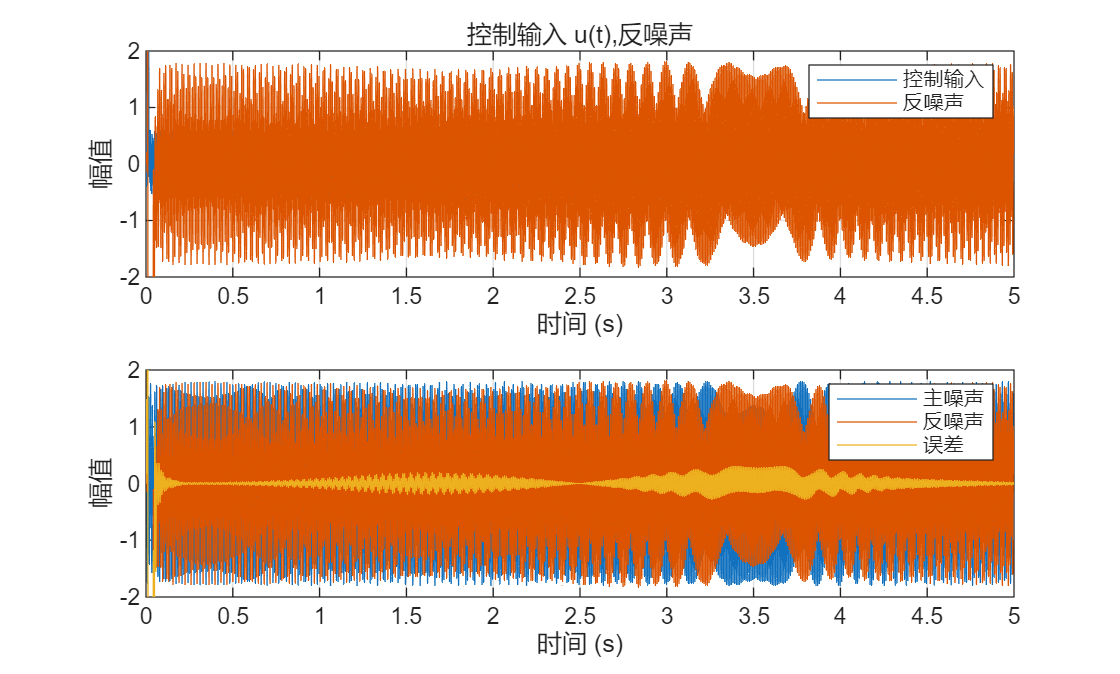

Q = zeros(1,nQ+1);
%% 自适应参数初始化
lambda1 = 0.98; % Forgetting factor
lambda2 = 1; % Adaptation gain
nB = length(B)-1;
nA = length(A);
nS = length(So);

Phi = zeros(1,nQ+1);
F = 10e3.*eye(nQ+1);

N = max([nA, nB, nS, length(Po)]);
U = zeros(1,N);
Y = zeros(1,N);
Yf = zeros(1,N);
W = zeros(1,N);
W1 = zeros(1,N);
W2 = zeros(1,N);

%% 自适应仿真循环
u = zeros(size(t)); % Control input
y = zeros(size(t)); % System output
antinoise = zeros(size(t));
w = zeros(size(t)); % Observer output
w1 = zeros(size(t));
w2 = zeros(size(t));
e0 = zeros(size(t)); % Adaptation error
e = zeros(size(t)); % Adaptation error

for k = 1:length(t)
    
    % Plant输出的测量
    antinoise(k) = FIR(B(2:end),U) - FIR(A(2:end),Yf);
    Yf = [antinoise(k), Yf(1:end-1)];
    y(k) = antinoise(k) + disturbance(k);
    Y = [y(k),Y(1:end-1)];

    % 扰动观测值
    w(k) = FIR(A, Y) - FIR(Bo_star, U);
    W = [w(k),W(1:end-1)];
    w1(k) = FIR(So, W) - FIR(Po(2:end), W1);
    W1 = [w1(k),W1(1:end-1)];
    % 先验/后验误差
    e0(k) = w1(k) - FIR(Q, Phi);
    % 自适应参数更新
    e(k) = e0(k)/(1+Phi*F*Phi.');
    Q = Q + (F * Phi' * e(k))';

    
    % 计算控制输入
    u(k) = -FIR(Ro, Y) - FIR(conv(conv(HR,HS),Q), W) - FIR(So(2:end), U);
    % 饱和 
    % u(k) = sat(u(k),5);
    U = [u(k), U(1:end-1)];
    
    % 为下一时刻做准备
    w2(k) =  FIR(conv(conv(HR,HS),Bo_star), W) - FIR(Po(2:end), W2);
    W2 = [w2(k), W2(1:end-1)];
    Phi = [w2(k), Phi(1:end-1)];
    F_new = lambda1.* inv(F) + lambda2 .* (Phi' * Phi);
    F_new = F_new + 1e-8*eye(size(F_new));
    F = inv(F_new);
    if any(isnan(F(:))) || any(isinf(F(:))) || rcond(F) < 1e-12
        error('F矩阵奇异或数值不稳定，脚本已终止。');
    end
end
%% 初始化绘图窗口
figure('Name','实时信号处理','NumberTitle','off');
subplot(2,1,1);
plot(t, u, 'DisplayName', '控制输入'); hold on;
plot(t, antinoise, 'DisplayName', '反噪声');
grid on;
title('控制输入 u(t),反噪声');
legend('show');
xlabel('时间 (s)'); ylabel('幅值');
xlim([0 t(end)]); 
ylim([-2 2]);
subplot(2,1,2);
plot(t, disturbance, 'DisplayName', '主噪声'); hold on;
plot(t, antinoise, 'DisplayName', '反噪声');
plot(t, y, 'DisplayName', '误差');
grid on;
legend('show');
xlabel('时间 (s)'); ylabel('幅值');
xlim([0 t(end)]); 
ylim([-2 2]);

### 4.3 LMS仿真

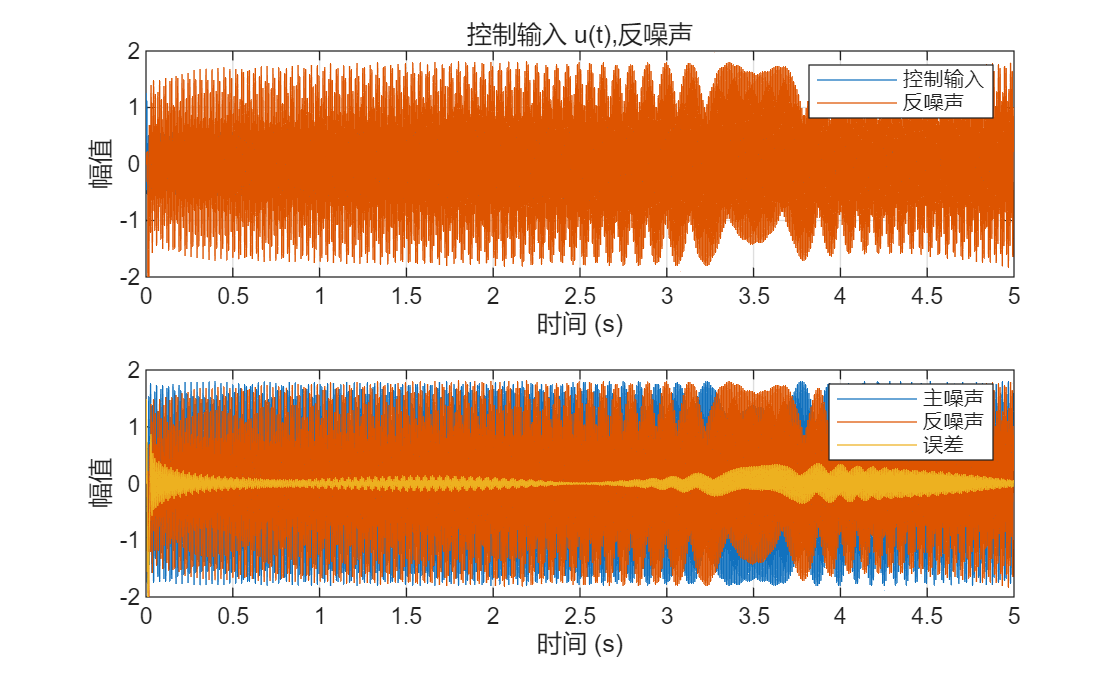

Q = zeros(1,nQ+1);
%% 自适应参数初始化
stepSize = 1e-2; 
nB = length(B)-1;
nA = length(A);
nS = length(So);

Phi = zeros(1,nQ+1);
F = 10e3.*eye(nQ+1);

N = max([nA, nB, nS, length(Po)]);
U = zeros(1,N);
Y = zeros(1,N);
Yf = zeros(1,N);
W = zeros(1,N);
W1 = zeros(1,N);
W2 = zeros(1,N);

%% 自适应仿真循环
u = zeros(size(t)); % Control input
y = zeros(size(t)); % System output
antinoise = zeros(size(t));
w = zeros(size(t)); % Observer output
w1 = zeros(size(t));
w2 = zeros(size(t));
e0 = zeros(size(t)); % Adaptation error
e = zeros(size(t)); % Adaptation error

for k = 1:length(t)
    
    % Plant输出的测量
    antinoise(k) = FIR(B(2:end),U) - FIR(A(2:end),Yf);
    Yf = [antinoise(k), Yf(1:end-1)];
    y(k) = antinoise(k) + disturbance(k);
    Y = [y(k),Y(1:end-1)];

    % 扰动观测值
    w(k) = FIR(A, Y) - FIR(Bo_star, U);
    W = [w(k),W(1:end-1)];
    w1(k) = FIR(So, W) - FIR(Po(2:end), W1);
    W1 = [w1(k),W1(1:end-1)];
    % 先验/后验误差
    e0(k) = w1(k) - FIR(Q, Phi);
    % 自适应参数更新（LMS）
    Q = Q + stepSize.* Phi* e0(k);

    % 计算控制输入
    u(k) = -FIR(Ro, Y) - FIR(conv(conv(HR,HS),Q), W) - FIR(So(2:end), U);
    U = [u(k), U(1:end-1)];
    
    % 为下一时刻做准备
    w2(k) =  FIR(conv(conv(HR,HS),Bo_star), W) - FIR(Po(2:end), W2);
    W2 = [w2(k), W2(1:end-1)];
    Phi = [w2(k), Phi(1:end-1)];
end

%% 初始化绘图窗口
figure('Name','实时信号处理','NumberTitle','off');
subplot(2,1,1);
plot(t, u, 'DisplayName', '控制输入'); hold on;
plot(t, antinoise, 'DisplayName', '反噪声');
grid on;
title('控制输入 u(t),反噪声');
legend('show');
xlabel('时间 (s)'); ylabel('幅值');
xlim([0 t(end)]); 
ylim([-2 2]);
subplot(2,1,2);
plot(t, disturbance, 'DisplayName', '主噪声'); hold on;
plot(t, antinoise, 'DisplayName', '反噪声');
plot(t, y, 'DisplayName', '误差');
grid on;
legend('show');
xlabel('时间 (s)'); ylabel('幅值');
xlim([0 t(end)]); 
ylim([-2 2]);